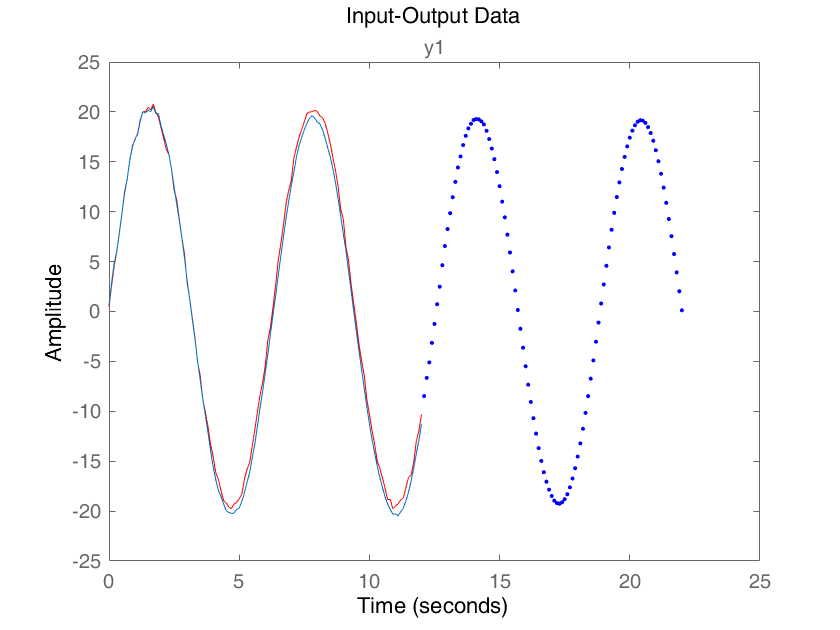

clear
clc
close all

% load iddata9 z9
% observed_data = z9(1:128); 
% Ts = observed_data.Ts;
% t = observed_data.SamplingInstants;
% y = observed_data.y;
% sys = ssest(observed_data,4,'Ts',Ts);
% H = 100;
% yh1 = forecast(sys,observed_data,H);
% A = sys.A;
% K = sys.K;
% C = sys.C;
% Predictor = idss((A-K*C),K,C,0,'Ts',Ts);
% x0 = findstates(sys,observed_data,1);
% Input = iddata([],y,Ts);
% opt = simOptions('InitialCondition',x0);
% [~,~,x] = sim(Predictor,Input,opt);
% xfinal = x(end,:)';
% x0_for_forecasting = Predictor.A*xfinal + Predictor.B*y(end);
% opt = simOptions('InitialCondition',x0_for_forecasting);
% Input = iddata([],zeros(H,0),Ts,'Tstart',t(end)+Ts);
% yh2 = sim(sys,Input,opt);
% plot(yh1,yh2,'r.')

t = 0:0.1:12; t = t';
pastdata = 20*sin(t) + rand([length(t) 1]);
pastdata = iddata(pastdata,'Ts',0.1,'Tstart',0);
sys = ar(pastdata,20);
Kp = 20;
yp = predict(sys,pastdata,Kp);
Kf = 100;
yf = forecast(sys,pastdata,Kf);
% figure
plot(pastdata,'r',yp,yf,'.');

predict函数与forecast函数使用功能对比_20190226

图中红色实线为测试获得的数据（历史数据）；

浅蓝色实线为predict函数输出，即用历史数据（pastdata）所拟合的模型的输出（一步预测），用以验证拟合模型的好坏；

深蓝色点线为forecast函数输出，即用所拟合的模型，对未来时间的预测。